# Analysis of Simulations

## Trajectorie

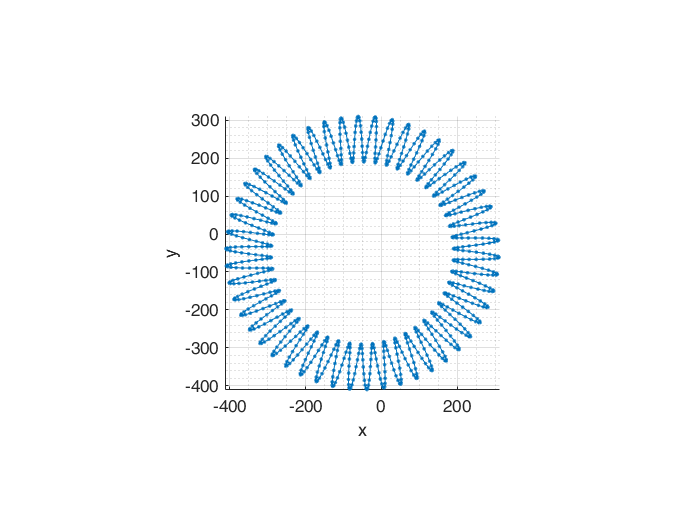

plot3(traj(1,:),traj(2,:),traj(3,:),'Marker','.','LineStyle','-')
xlabel('x');ylabel('y');zlabel('z')
grid on; grid minor;
axis vis3d; view([0 90]);rotate3d on;

## Vergleich Berechnung und Simulation

ticks = struct();
ticks.range = 0:pi/2:2*pi;
ticks.chars = {'0','pi/2','pi','3*pi/2','2*pi'};

### Vergleich der einzelnen Achsen

dxcord = traj(1,:)-simCordRS(1,:);
dycord = traj(2,:)-simCordRS(2,:);
dzcord = traj(3,:)-simCordRS(3,:);

#### absolute Entfernung der Punkte

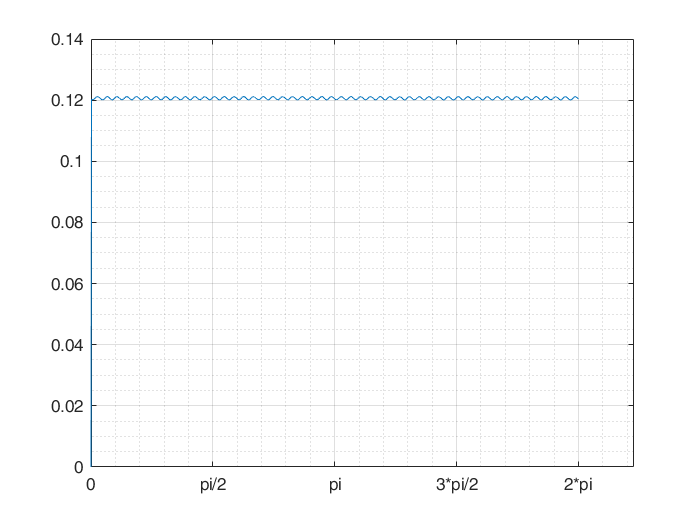

dcord = sqrt(dxcord.^2 + dycord.^2 + dzcord.^2);
plot(simAngRS,dcord)
setupPlot(ticks);
tiledlayout(3,1);

#### x-Achse

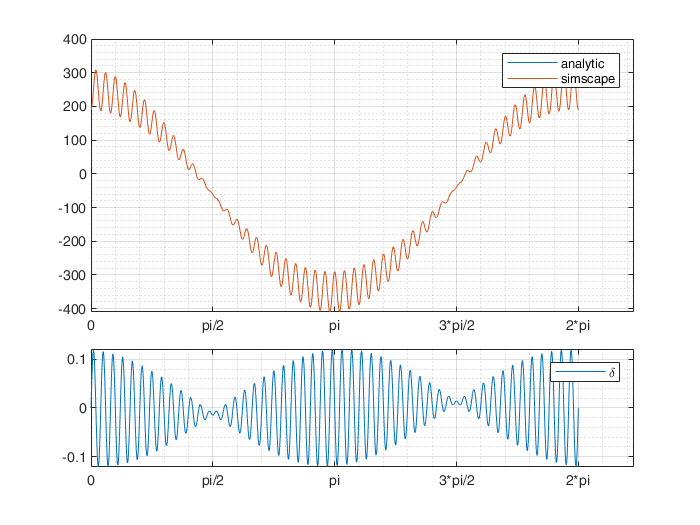

ax(1) = nexttile(1,[2 1]);
plot(simAngRS,[traj(1,:);simCordRS(1,:)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(3);

[dxmaxval,dxmaxloc] = findpeaks(dxcord,simAngRS,'MinPeakProminence',4);
mH = plot(simAngRS,dxcord);
if abs(dxmaxval)>1e-3
    line(dxmaxloc,dxmaxval,'Marker','|','LineStyle','none','Color','red');
    datatip(mH,dxmaxloc,dxmaxval);
end
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

#### y-Achse

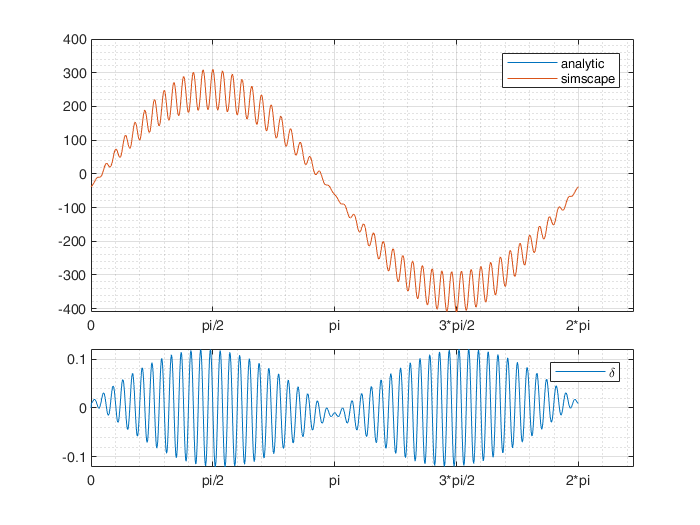

tiledlayout(3,1);
ax(1) = nexttile(1,[2 1]);
plot(simAngRS,[traj(2,:);simCordRS(2,:)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(3);

[dymaxval,dymaxloc] = findpeaks(dycord,simAngRS,'MinPeakProminence',4);
[dyminval,dyminloc] = findpeaks(-dycord,simAngRS,'MinPeakProminence',4);
mH = plot(simAngRS,dycord);
if abs(mean([dymaxval,dyminval])) > 1e-3
    line(dymaxloc,dymaxval,'Marker','|','LineStyle','none','Color','red');
    line(dyminloc,-dyminval,'Marker','|','LineStyle','none','Color','green');
    datatip(mH,dymaxloc,dymaxval);
    datatip(mH,dyminloc,-dyminval);
end
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

#### z-Achse

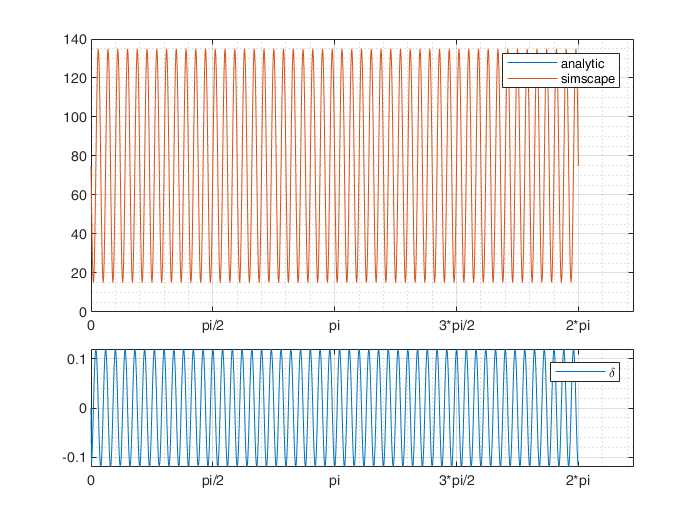

tiledlayout(3,1);
ax(1) = nexttile(1,[2 1]);
plot(simAngRS,[traj(3,:);simCordRS(3,:)])
setupPlot(ticks); legend('analytic','simscape');

ax(2) = nexttile(3);

plot(simAngRS,dzcord)
setupPlot(ticks); legend('\delta');
linkaxes(ax,'x')

### Gesamt

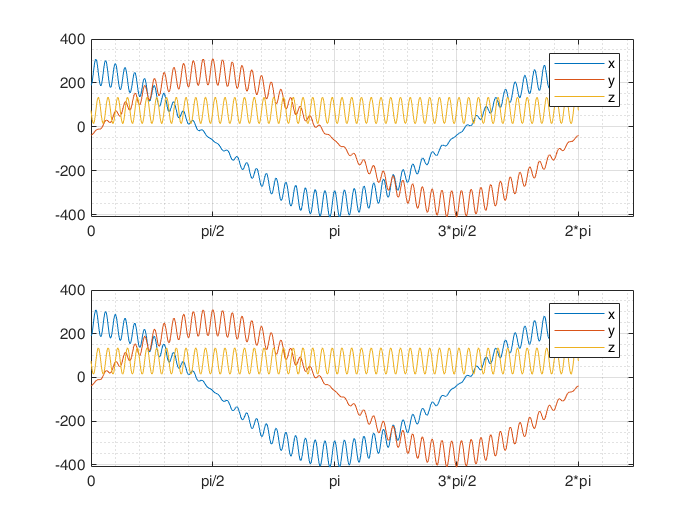

tiledlayout(2,1);
ax(1) = nexttile(1);
plot(simAngRS,traj);
legend('x','y','z')
setupPlot(ticks);
ax(2) = nexttile(2);
plot(simAngRS,simCordRS)
setupPlot(ticks);
legend('x','y','z')
linkaxes(ax,'x')

function setupPlot(ticks)
set(gca,'XTick',ticks.range)
set(gca,'XTickLabel',ticks.chars)

grid on;
grid minor;
end